# Create and Customize 3-D Swarm Charts

3-D swarm scatter charts are scatter plots with the points offset (jittered) in the x- and y-dimensions.

### Read Bicycle Data

We will use *bicycleData.mat* to demonstrate how to create and customize swarm charts. The MAT file contains bicycle traffic data over a period of time. First, use a helper function to load the data, process it and obtain variables that can be plotted.

[day,bikeCount,hourOfDay,direction] = readBicycleData;

### Basic 3-D Swarm Chart

View the distribution of bicycle traffic according to the day of the week split by Eastbound and Westbound traffic. 

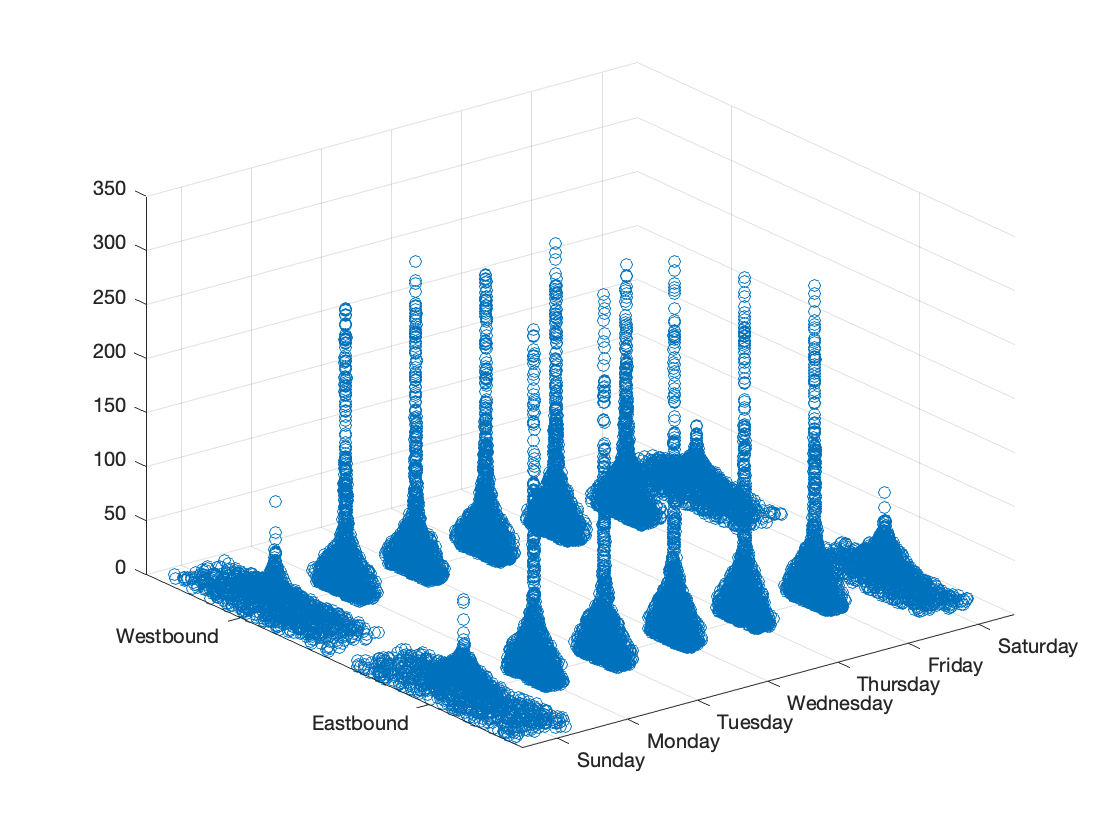

swarmchart3(day,direction,bikeCount);

## Customization

### Change Marker Properties

To specify the marker size and whether the marker is filled, use the 4th and 5th input arguments to `swarmchart3`.

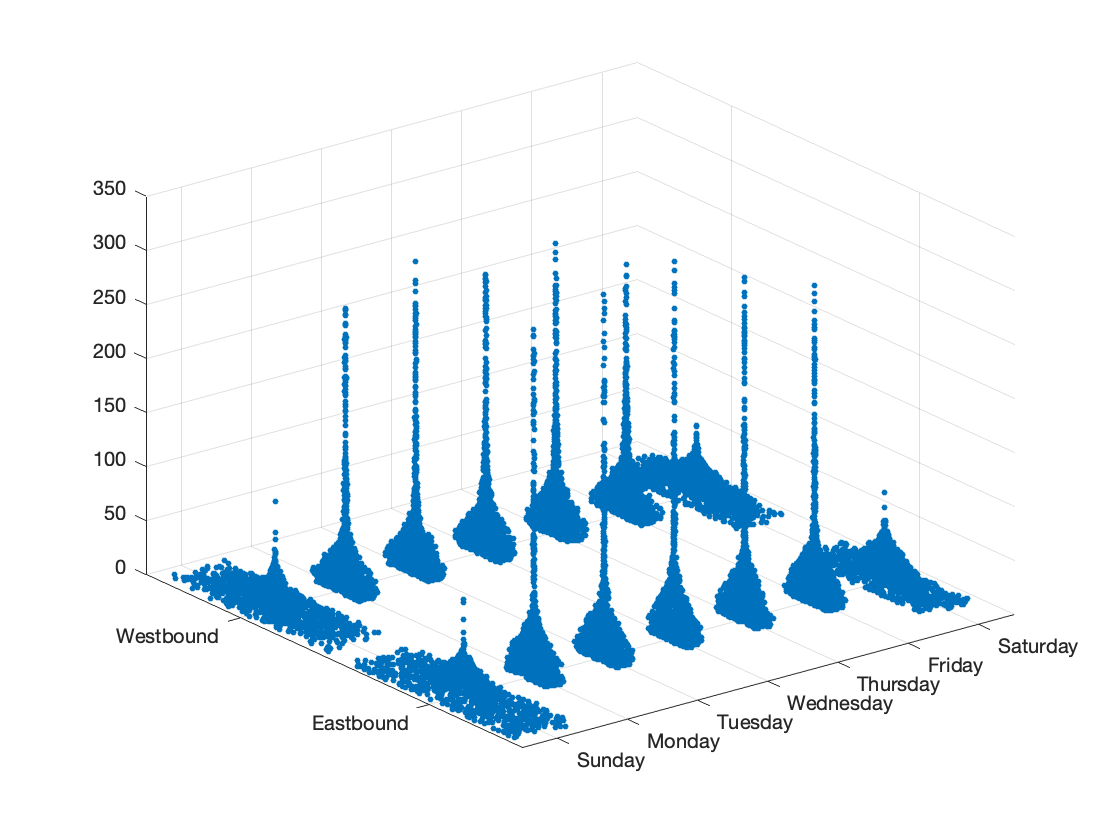

markerSize = 10;

s = swarmchart3(day,direction,bikeCount,...
    markerSize,...      % Specify marker size
    "filled");          % Specify marker as filled

### Display Filled Markers with Varied Color

The *c* input argument can be used to create varying marker colors. In this instance, the hour variable can be used to see how bicycle traffic changes by the hour on each day. The chart shows that traffic is predominantly Eastbound in the morning and Westbound in the evening.

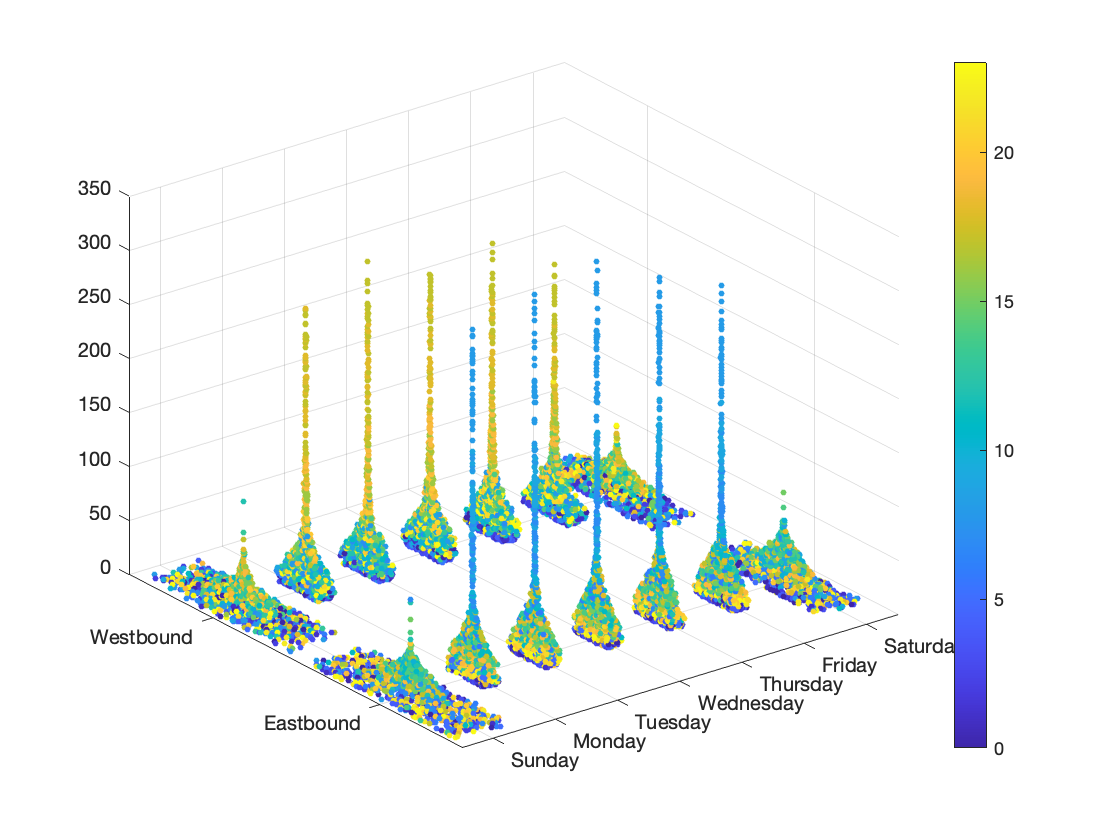

figure
s1 = swarmchart3(day,direction,bikeCount,...
    markerSize,...          
    hourOfDay,...     % Specify variable used to determine marker colors
    "filled");      
colorbar()       % Use colorbar to see how colors correspond to hours in the day

### Change Jitter Width

If the wide base of each cluster is undesired or reduces readability, use the jitter property *XJitterWidth *or* YJitterWidth* to limit the width. Add a label to the colorbar for clarity.

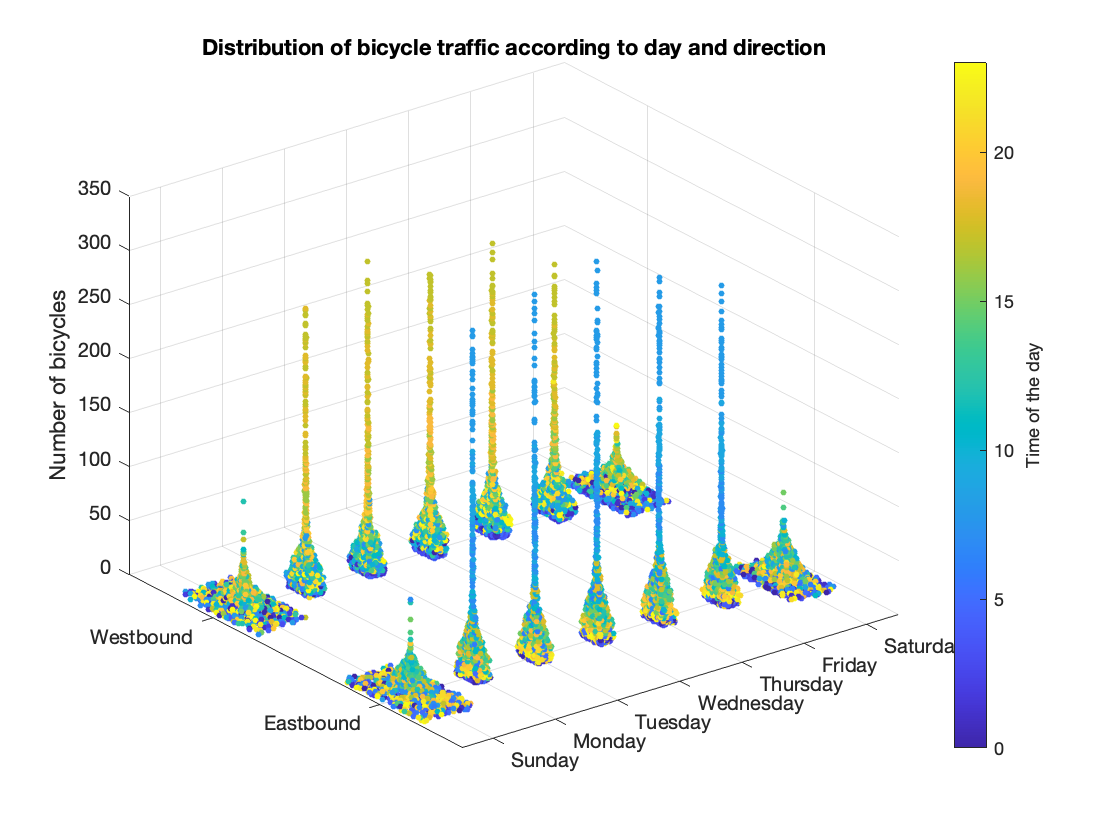

YJitterWidth = 0.5;

s2 = swarmchart3(day,direction,bikeCount,10,hourOfDay,"filled",...
    "YJitterWidth",YJitterWidth); % Specify YJitterWidth between 0 and 1
title("Distribution of bicycle traffic according to day and direction")
c = colorbar();
ylabel(c, "Time of the day");
zlabel("Number of bicycles");

## **Additional Information**

### **Get All Scatter Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Scatter object, uncomment the following code. View or modify these properties using dot notation.

% get(s)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[swarmchart3](https://www.mathworks.com/help/matlab/ref/swarmchart3.html)

### Helper Functions

This helper function reads in bicycle data and processes the data to generate four variables:

- bikeCount - Total number of bicycles recorded in a given hour on a given day, going in a particular direction

- hour - Hour of the day corresponding to each recorded number of bicycles

- day - Day of the week corresponding to each recorded number of bicycles

- direction - Direction of travel corresponding to each recorded number of bicycles

function [day, bikeCount, hours, direction] = readBicycleData()
    load bicycleData.mat bicycleData;
    daynames = ["Sunday" "Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday"];
    dirNames = ["Eastbound"; "Westbound"];
    day = repmat(categorical(bicycleData.Day,daynames),[2,1]); % Duplicate Day column 
    hours = repmat(hour(bicycleData.Timestamp),[2,1]); % Duplicate Timestamp column
    direction = categorical(repelem(dirNames,length(bicycleData.Day))); % Create column vector of two direction categories
    bikeCount = [bicycleData.Eastbound; bicycleData.Westbound]; % Vertically concatenate Eastbound and Westbound traffic values
end

Copyright (c) 2021, The MathWorks, Inc.